## Load data

clear;

cupId = 3;

% Load file and cup configurations
[~, cup] = func_loadBasicParams(cupId);

% Data cofigurations
config.data.ch = 1;
config.data.rate = 192000; 

config.data.unit = 50; 

config.data.nLoc = 4;
config.data.nTrialPerLoc = 10;
config.data.nTrial = config.data.nLoc * config.data.nTrialPerLoc; 

config.data.nData = (ceil(cup.maxAmount / config.data.unit) + 1) * config.data.nTrial; 

% Load data
load([num2str(cupId), 'cup_metal.mat']);

## Split dataset for calibration

% Training / test split
config.calib.nTrain = 2;
config.calib.nTrialPerTrain = 2;
config.calib.locSet = [1];

idx = ceil(linspace(1, config.data.nData / config.data.nTrial, config.calib.nTrain)); % Train data 선형 벡터 생성

idxFilter = false(1, config.data.nData); % 전체 0 
for cnt = idx
    for cnt2 = config.calib.locSet
        idxFilter((cnt - 1) * config.data.nTrial ...
            + (cnt2 - 1) * config.data.nTrialPerLoc ...
            + randperm(config.data.nTrialPerLoc, config.calib.nTrialPerTrain)) = true;
    end
end

train = data(idxFilter);
test = data(~idxFilter);

amount = unique([train(:).amount]);
for cnt = amount
    test([test(:).amount] == cnt) = [];
end

## Calibration

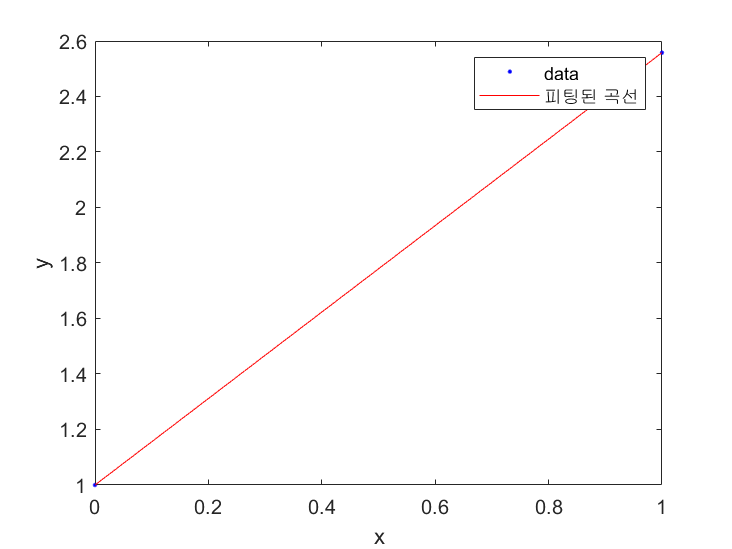

config.calib.fL = 200;
config.calib.fH = 2500;

config.detect.order = 4;
config.detect.energyWidth = config.data.rate * .01;
config.detect.searchRange = config.data.rate * .5;
config.detect.threshold = [.5, .01];

config.extract.nfft = config.data.rate * 1;
config.extract.f = (1:config.extract.nfft/2) ./ config.extract.nfft * config.data.rate;
config.extract.marginRatio = .01; 

[b, a] = butter(config.detect.order, [config.calib.fL, config.calib.fH] / config.data.rate * 2, 'bandpass');

for cnt = 1:length(train)
    cur = train(cnt).raw(:, config.data.ch);       
    train(cnt).detected = func_detectSingingSound(cur, b, a, config);
    
    tmp = abs(fft(train(cnt).detected, config.extract.nfft));
    train(cnt).spec = tmp(2:config.extract.nfft / 2 + 1);
end

calib = struct();
for cnt = 1:config.calib.nTrain
    curIdx = (cnt - 1) * config.calib.nTrialPerTrain + (1:config.calib.nTrialPerTrain);
    
    calib.amount(cnt) = train(curIdx(1)).amount;
    
    tmp = mean([train((cnt - 1) * config.calib.nTrialPerTrain + (1:config.calib.nTrialPerTrain)).spec], 2);
    if cnt == 1
        [~, calib.f(cnt, :)] = max(tmp);
    else
        [~, calib.f(cnt, :)] = max(tmp(1:max(calib.f(cnt - 1))));
    end
end

calib.f = config.extract.f(calib.f);
calib.fH = calib.f(1);
calib.fL = calib.f(end);
calib.n = 2;

calib.french= func_computeFrenchParams(calib.amount', calib.f', calib.fH, cup.maxAmount, calib.n); % A.P French's Formula


figure
plot(calib.french.f, calib.french.x, calib.french.y)

## Extract features in test dataset

[b, a] = butter(config.detect.order, ...
    [min(calib.fL) * (1 - config.extract.marginRatio), max(calib.fH) * (1 + config.extract.marginRatio)] / config.data.rate * 2, ...
    'bandpass');

for cnt = 1:length(test)
    cur = test(cnt).raw(:, config.data.ch);    
    test(cnt).detected = func_detectSingingSound(cur, b, a, config);
    
    tmp = abs(fft(test(cnt).detected, config.extract.nfft));
    test(cnt).spec = tmp(2:config.extract.nfft / 2 + 1);
end

## Generate evaluate set

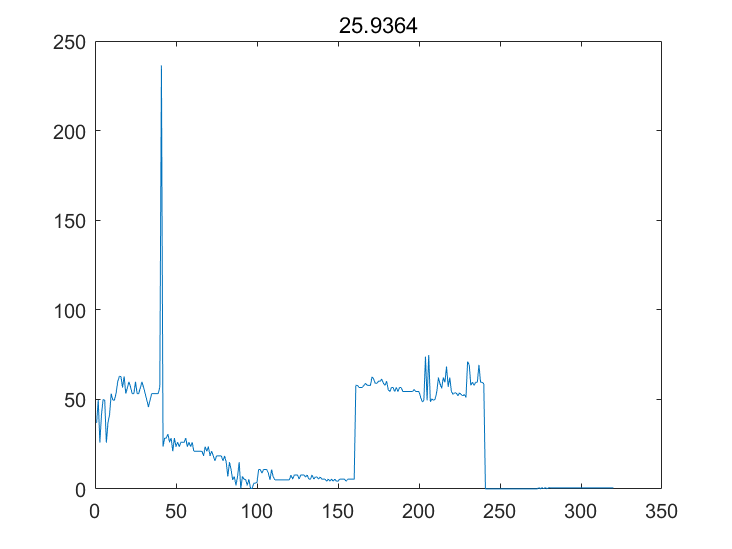

config.eval.nTrial = 5;
if config.eval.nTrial == 1
    config.eval.nRepeat = config.data.nTrialPerLoc;
else
    config.eval.nRepeat = 10;
end

config.eval.locSet = [1, 2, 3, 4];
config.eval.amountSet = unique([test(:).amount]);

evaluate = struct();
idx = 1;

for cnt = 1:length(config.eval.amountSet)    
    cur = test([test(:).amount] == config.eval.amountSet(cnt));
    
    for cnt2 = 1:length(config.eval.locSet)
        curLoc = cur([cur(:).location] == config.eval.locSet(cnt2));
        
        for cnt3 = 1:config.eval.nRepeat
            evaluate(idx).amount = config.eval.amountSet(cnt);
            evaluate(idx).location = config.eval.locSet(cnt2);
            
            selected = randperm(config.data.nTrialPerLoc, config.eval.nTrial);
            evaluate(idx).spec = mean([curLoc(selected).spec], 2);
            
            [~, evaluate(idx).f] = max(evaluate(idx).spec);
            evaluate(idx).f = config.extract.f(evaluate(idx).f);          
            
            evaluate(idx).eAmount = func_estimateAmountUsingFrench(calib.french.f.a, ...
                 evaluate(idx).f, calib.fH, cup.maxAmount, calib.french.n);                
            evaluate(idx).error = abs(evaluate(idx).amount - evaluate(idx).eAmount);
            
            idx = idx + 1;
        end
    end
end

figure
plot([evaluate(:).error])
title(mean([evaluate(:).error]))